# Predictive Control for Cobot Safety

*Could add in a short introductory description of the aims of the project and such*

## Robot Plant and Initial Conditions

Load the KINOVA Gen 3 robot manipulator multibody model and rigid body tree.

clear; clc;
[robotRBT, robotInformation] = loadrobot("kinovaGen3", "DataFormat", "column", "Gravity", [0 0 -9.81]);

Define key robot parameters that will be used further on. The quantity of joints and the end-effector (tool) element of the rigid body tree.

joint_qty = numel(homeConfiguration(robotRBT));
endEff = 'EndEffector_Link';

Prepare inverse kinematic equations to compute robot configurations given end-effector poses.

robot_InverseKinematics = inverseKinematics("RigidBodyTree", robotRBT);
robot_InverseKinematics.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

Define initial and final trajectory task-space coordinates. The initial position may be given as a complete robot configuration while the final position is a desired end-effector pose (other joint positions in the task-space are irrelevant).

qInit = [0 0 0 0 0 0 0]'*pi/180; % initial joint configuration in radians
taskInit = getTransform(robotRBT, qInit, endEff); % initial transformation matrix of task
coordStart = taskInit(1:3, 4); % initial task-space end-effector coordinates XYZ

taskEnd = trvec2tform([0.6 0.4 0.3])*axang2tform([0 1 0 pi]); % final task-space end-effector coordinates XYZ
anglesEnd = rotm2eul(taskEnd(1:3, 1:3), "XYZ"); % final task-space end-effector rotational coordinates [phi theta psi]
poseEnd = [taskEnd(1:3, 4); anglesEnd']; % final pose vector [X Y Z phi theta psi]

## Static and Dynamic Obstacles

Generate static obstacles that represent elements of the environment.

staticObstacleGeneration;

Define primary task-driven waypoints for the dynamic obstacle. In this case, the representative collaborative partner and obstacle will be a robot model aiming to reach the waypoints with an end-tool.

task_waypoints = [0.7 0.4 0.3; 
    0.4 0.0 0.3; 
    0.8 -0.2 0.4; 
    0.8 -0.2 0.7;
    0.5 -0.3 0.8;
    0.8 -0.4 0.7;
    0.8 -0.4 0.4;
    0.4 -0.5 0.3;
    0.4 0.1 0.3;
    0.7 0.4 0.3];

Generate dynamic obstacle representing the collaborative element to the plant. This model will represent a human working alongside the KinovaGen3 robot.

dynamicObstacleGeneration;

Generate the task trajectory for the obstacle robot to follow desired waypoints during the simulation.

dynamicObstacleTrajectoryGeneration;

   4.3000e-06

    3.4548

    9.0514

   15.3499

   18.4359

   22.8540

   26.2465

   30.1449

   34.1104

   39.5136



## Initial Visualization

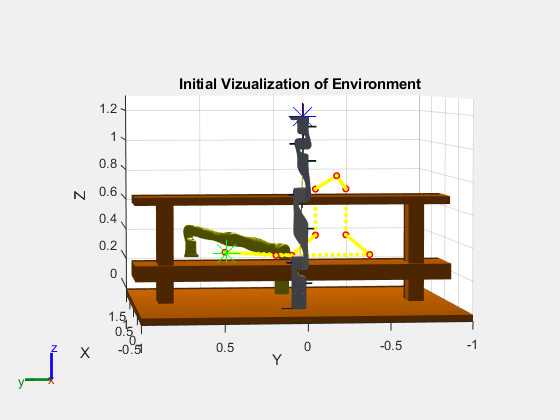

figure('Name', 'Initial Robot and Obstacle Conditions');

% display the robot rigid body tree at the initial joint configuration
show(robotRBT, qInit(:, 1), 'PreservePlot', false, 'Frames', 'on');
axis([-0.5 1.5 -1.0 1.0 -0.04 1.3])
view([-90 10 5]);
title('Initial Vizualization of Environment')
hold on

% display a marker of the starting end-effector position
plot3(coordStart(1), coordStart(2), coordStart(3), 'b*', 'MarkerSize', 20);

% display a marker of the final end-effector position
plot3(poseEnd(1), poseEnd(2), poseEnd(3), 'g*', 'MarkerSize', 20);

% display static obstacles
for i=1:length(staticObst)
    [~, posObs] = show(staticObst{i});
end

% display dynamic obstacles
obst_dynamic = show(obst_robot, obst_robot_config, 'PreservePlot', false, 'Frames', 'off', 'Position', [1 0 0 pi/2]);
for i=1:(joint_qty+1)
    obst_dynamic.Children(i).FaceColor = 'y';
end
for i=1:height(task_waypoints)
   plot3(task_waypoints(i, 1), task_waypoints(i, 2), task_waypoints(i, 3), 'r.', 'MarkerSize', 15); 
end
for i=1:height(waypoints)
    plot3(waypoints{i}(1,4), waypoints{i}(2,4), waypoints{i}(3,4), 'y.', 'MarkerSize', 10); 
end
hold off

## Design: PID Control

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation

figure('Name', 'Task Simulation');

% visualize obstacle robot configuration
show(obst_robot, obst_robot_config, "PreservePlot", false, "Frames", "off");
axis([-0.5 1.5 -1.0 1.0 -0.04 1.3])
view([-90 10 5]);
hold on

% display static obstacles
for i=1:length(staticObst)
    [~, posObs] = show(staticObst{i});
end

% display obstacle waypoints
for i=1:height(waypoints)
    plot3(waypoints{i}(1,4), waypoints{i}(2,4), waypoints{i}(3,4), 'y.', 'MarkerSize', 10); 
end

% % track dynamic obstacle poses
% obst_poses = zeros(4, 4, length(t));
% 
% % iteratively simulate robot state changes
% for i = 1:length(t)
%     disp(i)
%     % % interpolate simulated dynamic obstacle joint positions for current configuration
%     % obst_configCurr = interp1(obst_task_t, obst_task_state(:, 1:joint_qty), t(i))';
%     % obst_poseCurr = getTransform(obst_robot, obst_configCurr, endEff);
%     % obst_poses(:,:,i) = obst_poseCurr;
% 
%     % display changes within the plot
%     show(obst_robot, obst_task_state(i, 1:joint_qty)', "PreservePlot", false, "Frames", "off");
% 
%     % % plot path taken
%     % obst_path = plot3(squeeze(obst_poses(1,4,1:i)), squeeze(obst_poses(2,4,1:i)), squeeze(obst_poses(3,4,1:i)), 'b');
%     drawnow;
% end

% pre-defined matrix of joint configurations at each waypoint
qs = zeros(length(waypoints), joint_qty);

for i = 1:length(waypoints)
    tDes = waypoints{i};
    [q_sol, q_info] = obst_robot_InverseKinematics(endEff, tDes, weights, obst_robot_config);

    % Display status of inverse kinematics results
    disp(q_info.Status);

    % store configuration
    qs(i, :) = q_sol(1:joint_qty);

    % prepare baseline configuration for next iteration
    obst_robot_config = q_sol;
end

best available
best available
best available
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
success
success
success
success
success
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
best available
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
success
s

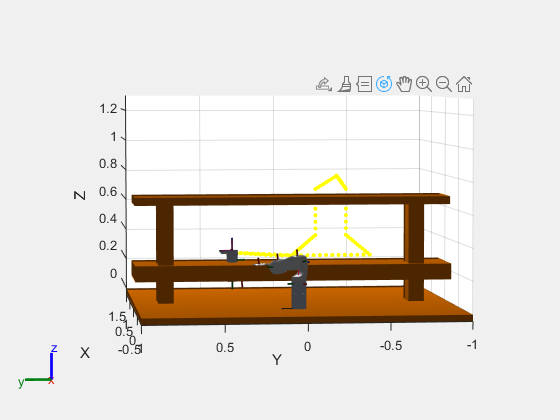



% animate
fps = 30;
r = robotics.Rate(fps);
for i = 1:length(waypoints)
    show(obst_robot, qs(i,:)', 'PreservePlot', false);
    drawnow;
    waitfor(r);
end
hold off

## Design: Linear MPC

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation

## Design: Non-linear MPC

### Closed-Loop Trajectory Planning

### Joint-Space Simulation

### Final Visual Simulation